# Drawing Tools

This document is meant to experiment and improve upon drawing tools already generated. The end goal is to have a tool to automatically generate drones in given positions along a preplanned trajectory.

Much of this code was originally developed by Sean and bob doing some parts - I'll be incorporating and cleaning these up.

interceptor = create_quadcopter([1, 1, 1], [0 0 0], .4, .08, 'blue', 'green', 'blue')

interceptor = struct with fields:
          arm_length: 0.4000
           prop_size: 0.0800
          arms_color: 'blue'
         props_color: 'green'
    trajectory_color: 'blue'
                 xyz: [1 1 1]
            rotation: [0 0 0]


target = create_quadcopter([0.5, 0.5, 2], [0 0 0], .2, .04, 'red', 'black', 'red')

target = struct with fields:
          arm_length: 0.2000
           prop_size: 0.0400
          arms_color: 'red'
         props_color: 'black'
    trajectory_color: 'red'
                 xyz: [0.5000 0.5000 2]
            rotation: [0 0 0]



tspan = 0:.5:10;
x = sin(tspan)-1;
y = tspan*0.25 + 1;
z = sin(tspan/2) + 1;
xyz = [x; y; z;]

xyz =    -1.0000   -0.5206   -0.1585   -0.0025   -0.0907   -0.4015   -0.8589   -1.3508   -1.7568   -1.9775   -1.9589   -1.7055   -1.2794   -0.7849   -0.3430   -0.0620   -0.0106   -0.2015   -0.5879   -1.0752   -1.5440
    1.0000    1.1250    1.2500    1.3750    1.5000    1.6250    1.7500    1.8750    2.0000    2.1250    2.2500    2.3750    2.5000    2.6250    2.7500    2.8750    3.0000    3.1250    3.2500    3.3750    3.5000
    1.0000    1.2474    1.4794    1.6816    1.8415    1.9490    1.9975    1.9840    1.9093    1.7781    1.5985    1.3817    1.1411    0.8918    0.6492    0.4284    0.2432    0.1050    0.0225    0.0007    0.0411


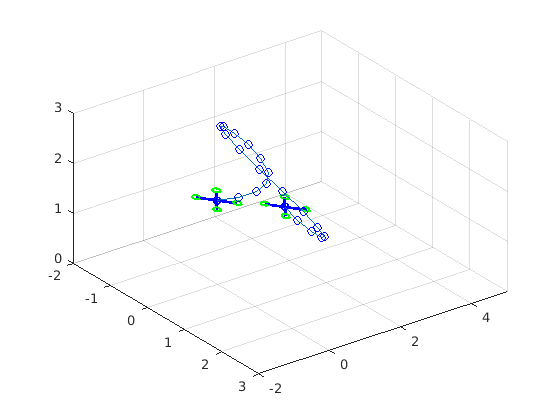


states = [];
for t = 1:length(tspan)
    states = [states create_quadcopter(transpose(xyz(:,t)), [0 0 0], .4, .08, 'blue', 'green', 'blue')];
end

figure
hold on
view(60,10)
grid on
xlim([-2, 3])
ylim([-2,5])
zlim([0,3])
hold on;

% plot_quadcopter(interceptor);
% plot_quadcopter(target);

plot_quadcopter_trajectory(states);

hold off

## Functions

### create_quadcopter

create_quadcopter creates a quadcopter struct object for tracking stats abouts the quadcopter for easily handling. It also tracks the current xyz

function quadcopter = create_quadcopter(xyz, rotation, arm_length, prop_size, arms_color, props_color, trajectory_color)
    quadcopter = struct("arm_length", arm_length, "prop_size", prop_size, ...
        "arms_color", arms_color, "props_color", props_color, ...
        "trajectory_color", trajectory_color, ...
        "xyz", xyz, "rotation", rotation);
end

### quadcopter_rotation

quadocopter_rotation will, given a quadcopter, return the roll pitch yaw rotation matrix for the current orientation.

function R = quadcopter_rotation(quadcopter)
    phi = quadcopter.rotation(1);
    theta = quadcopter.rotation(2);
    psi = quadcopter.rotation(3);
    R=[cos(theta)*cos(psi) sin(phi)*sin(theta)*cos(psi)-cos(phi)*sin(psi) sin(phi)*sin(psi)+cos(phi)*sin(theta)*cos(psi);
    cos(theta)*sin(psi) cos(phi)*cos(psi)+sin(phi)*sin(theta)*sin(psi) cos(phi)*sin(theta)*sin(psi)-sin(phi)*cos(psi);
    -sin(theta) sin(phi)*cos(theta) cos(phi)*cos(theta)];
end

### update_quadcopter

update_quadcopter takes a quadcopter and a $\dot{z}$ and returns a quadcopter with updated values

function quadcopter = update_quadcopter(quadcopter, zdot)
    delta_xyz = [zdot(1); zdot(2); zdot(3);];
    delta_rotation = [zdot(4); zdot(5); zdot(6);],
    quadcopter = move_quadcopter(quadcopter, delta_xyz, delta_rotation);
end

### move_quadcopter

move_quadcopter takes a quadcopter and a given delta xyz and delta rotation. These move the quadcopter the given delta from its current position/orientation to its resulting new one. Because MATLAB is pass by value, it returns a new quadcopter struct.

function quadcopter = move_quadcopter(quadcopter, delta_xyz, delta_rotation)
    quadcopter.xyz = quadcopter.xyz + delta_xyz;
    quadcopter.rotation = quadcopter.rotation + delta_rotation;
end

### plot_quadcopter

plot_quadcopter will take a given a quadcopter struct object. From this object it will ascertain the XYZ center origin of a drone (center of mass), and given roll, pitch, yaw orientation (in radians). It assumes that a figure is already active to be drawing in.

It will return the resutling graphics handles for optional cleanup in case of animation. Color options that can be passed in are optional, in the event of desired variability in copter design.

function handles = plot_quadcopter(quadcopter)
    handles = [];

    center = quadcopter.xyz;
    r = quadcopter.prop_size;
    rotate = quadcopter_rotation(quadcopter);
    l = quadcopter.arm_length;
    
    z = [0;0;1];
    
    norm = transpose(r*z);
    
    %the base quad setup at zero
    LF0 = [l*cos(pi/4);l*sin(pi/4);0];
    LR0 = [l*cos(3*pi/4);l*sin(3*pi/4);0];
    RR0 = [l*cos(5*pi/4);l*sin(5*pi/4);0];
    RF0 = [l*cos(7*pi/4);l*sin(7*pi/4);0];
    
   %Quad rotated through R matrix
    LF = [center; [center+transpose(rotate*LF0)]];
    LR = [center; [center+transpose(rotate*LR0)]];
    RR = [center; [center+transpose(rotate*RR0)]];
    RF = [center; [center+transpose(rotate*RF0)]];
    
    %plotting
    handles = [plot3(center(1), center(2), center(3),"-bo", "LineWidth", 2, 'Color', quadcopter.arms_color)];
    handles = [handles; plot3(LF(:,1), LF(:,2),LF(:,3),"-", "LineWidth", 2, 'Color', quadcopter.arms_color)];
    handles = [handles; plot_circle_3d(LF(2,:), norm,r, quadcopter.props_color)];
    handles = [handles; plot3(LR(:,1), LR(:,2),LR(:,3),"-", "LineWidth", 2, 'Color', quadcopter.arms_color)];
    handles = [handles; plot_circle_3d(LR(2,:),norm,r, quadcopter.props_color)];
    handles = [handles; plot3(RR(:,1), RR(:,2),RR(:,3),"-", "LineWidth", 2, 'Color', quadcopter.arms_color)];
    handles = [handles; plot_circle_3d(RR(2,:), norm,r, quadcopter.props_color)];
    handles = [handles; plot3(RF(:,1), RF(:,2),RF(:,3),"-", "LineWidth", 2, 'Color', quadcopter.arms_color)];
    handles = [handles; plot_circle_3d(RF(2,:), norm,r, quadcopter.props_color)];

end

### plot_circle_3d

plot_circle_3d takes a circle center, its normal vector, and a radius. It then draws the resulting circle in 3d space at the correct orientation.

function h=plot_circle_3d(center,normal,radius, color)
    theta=0:0.01:2*pi;
    v=null(normal);
    points=repmat(center',1,size(theta,2))+radius*(v(:,1)*cos(theta)+v(:,2)*sin(theta));
    h=plot3(points(1,:),points(2,:),points(3,:),'-',  "LineWidth", 2, 'Color', color);
end

### plot_quadcopter_trajectory

plot_quadcopter_trajectory takes a an array of quadcopter structs, each representing a state of the quadcopter at a given point in time. From this, it will generate a list of XYZ center points denoting where the quadcopter is, a list of roll pitch yaw rotations. It plots the points of the trajectory as a dotted line of the quadcopter's specified trajectory color. It will plot the quadcopter at the beginning and end of the path.

function handles = plot_quadcopter_trajectory(quadcopter_states)
    % First plot the trajectory
    handles = [];
    xyzs = zeros(3, length(quadcopter_states));
    for i = 1:length(quadcopter_states)
        xyzs(:, i) = quadcopter_states(i).xyz;
    end
    plot3(xyzs(1,:), xyzs(2,:), xyzs(3,:), "-o", "MarkerSize", 6, "MarkerEdgeColor", quadcopter_states(1).trajectory_color);
    
    % Now plot the start and finish
    plot_quadcopter(quadcopter_states(1));
    plot_quadcopter(quadcopter_states(length(quadcopter_states)));
end